# Manual control of tank level and the need for PI control (with delay)

This livescript is a brief manual in support of the app ***tank_and_manual_vs_PIcontrol_delay.  ***It builds on earlier apps*** tanklevel_and_PIcontrol.mlapp, tanklevelbehaviour.mlapp***  which focussed on understanding the modelling and behaviour of simple tank level models, subject to changes in the core parameters such as tank volume, flow rate,  disturbances to the inlet flow and blockages in the outlet pipe. 

This file asks, how do we ensure we have the desired level, irrespective of the unnknown disturbances and changes in system parameters? These notes give the engineering and analytical background but more specifically the focus is on manual vs automated control, that is, the user is encouraged to experiment with manual control and from this observe the need for and benefits of an automated approach; here PI is provided. For completeness, the app also includes measurement delay which is a common industrial factor and makes manual control even more challenging.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Context of the tank system

- Using the app for manual control

- Using the app for PI control

## 1. Context of the tank level system and requirements

The figure below shows the maximum extent of the tank dimensions, so a width of upto 10 and a depth of 9. 

- The width/area can be modified by the user. 

- The water exits the tank from the outlet in the bottom right which has variable dimensions (linked to a conductance term *R*), again adjustable by the user. 

- The red rectangle represents a plug or bung which, from time to time moves down and acts as a blockage on the outlet pipe thus reducing its area and  the corresponding outflow. The user can also vary the percentage overlap of this bung with the outlet.

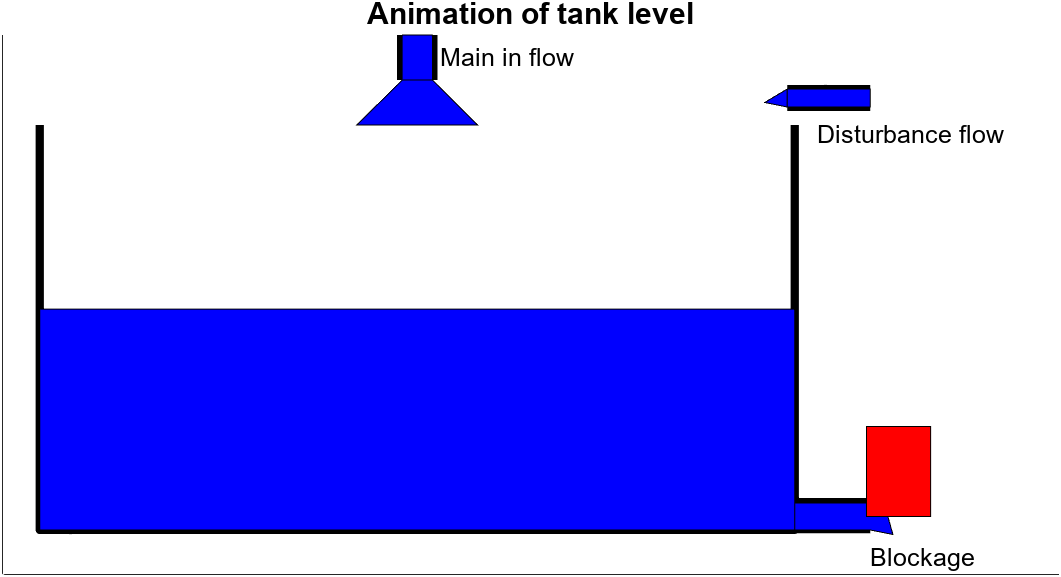

There are two input flows:

- the flow in the top centre is a controllable flow which the user adjusts to achieve the desired depth. This flow could be selected via open-loop or closed-loop mechanisms.

- the flow on the top right is a disturbance flow which again can be varied by the user. 

### 1.1 Model of the tank system

Assume cross-sectional area *A* and that the flow out is dependent on the depth *h* through a conductance parameter *R*. Then, using a volume balance the equation for the depth is governed by;


$$A\frac{\textrm{dh}}{\textrm{dt}}+\textrm{Rh}=f_{\textrm{in}} ;\;\;\;\;f_{\textrm{in}} =f+d;\;\;\;\;\;\;\equiv \;\;\;\;\;\;G\left(s\right)=\frac{1}{\textrm{As}+R}$$


where the flow in comprises the two components: *f* for controllable flow and *d* for disturbance flow. Blockage of the outlet pipe reduces the value of parameter *R*. A simple model for the tank behaviour is derived using the time constant form below (assuming constant in flows). 

$\frac{A}{R}\frac{\textrm{dh}}{\textrm{dt}}+h=\frac{1}{R}\left(f+d\right),\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;T=\frac{A}{R},\;\;\textrm{Gain}=\frac{1}{R}$; 

$h\left(t\right)=$$\frac{1}{R}\left(f+d\right)-$$\left(h\left(0\right)-\frac{1}{R}\left(f+d\right)\right)$$e^{-\frac{t}{T}}$;           $h_{\textrm{ss}} =\frac{f+d}{R}$

where $h_{\textrm{ss}}$ is the steady-state depth.

### 1.2 Uncertainties

There are two main uncertainties which impact on the level in the tank.

The disturbance flow d has an obvious effect on the steady-state in that a change in disturbance flow leads to a change in the steady-state depth as follows: $\delta h_{\textrm{ss}} =\frac{d}{R}$

A blockage (denoted as a fraction between 0 and 1) impacts on the conductance term* R and thus* it impacts on both the steady-state and the time constant.

$T=\frac{A}{R\left(1-B\right)},\;\;\textrm{Gain}=\frac{1}{R\left(1-B\right)}$; ${\;\;\;\;\;\;\;\;h}_{\textrm{ss}} =\frac{f+d}{R\left(1-B\right)}$

Hence an increase in the blockage term *B* causes an increase in the steady-state and an increase in the time constant. Note in this case the transfer function model would become:

$G\left(s\right)=\frac{\textrm{Gain}}{\textrm{Ts}+1}$ where  notionally   $h\left(s\right)=G\left(s\right)\left\lbrack f\left(s\right)+d\left(s\right)\right\rbrack$

### 1.3 Performance requirements

The performance requirement is set quite simply as, get the tank to a desired target depth ***H***. For simplicitly the app mostly has this level as a fixed value of ***H=8*** (defined in the preliminary section of the mlapp file so it can be changed).  

Users can experiment with PI design and also the impact on the design efficacy of both parameter changes (*A* and *R*) and also disturbances and blockages.

### 1.4 PI design 

We wish to control the depth in the tank to the target ***H*** by moving the in-flow. To do this a PI compensator is used :


$$f\left(s\right)=\left(K_p +\frac{K_i }{s}\right)\left(H\left(s\right)-h\left(s\right)\right)=C\left(s\right)\left(H\left(s\right)-h\left(s\right)\right)$$


Standard control threory will tell readers that including the integral will ensure offset free tracking in the steady-state, and because the model is first order, stability is assured. However, we still need to determine sensible values for the compensator coefficients.

Users can explore the impact of changing the two PI parameters on closed-loop behaviour and the performance requirements.

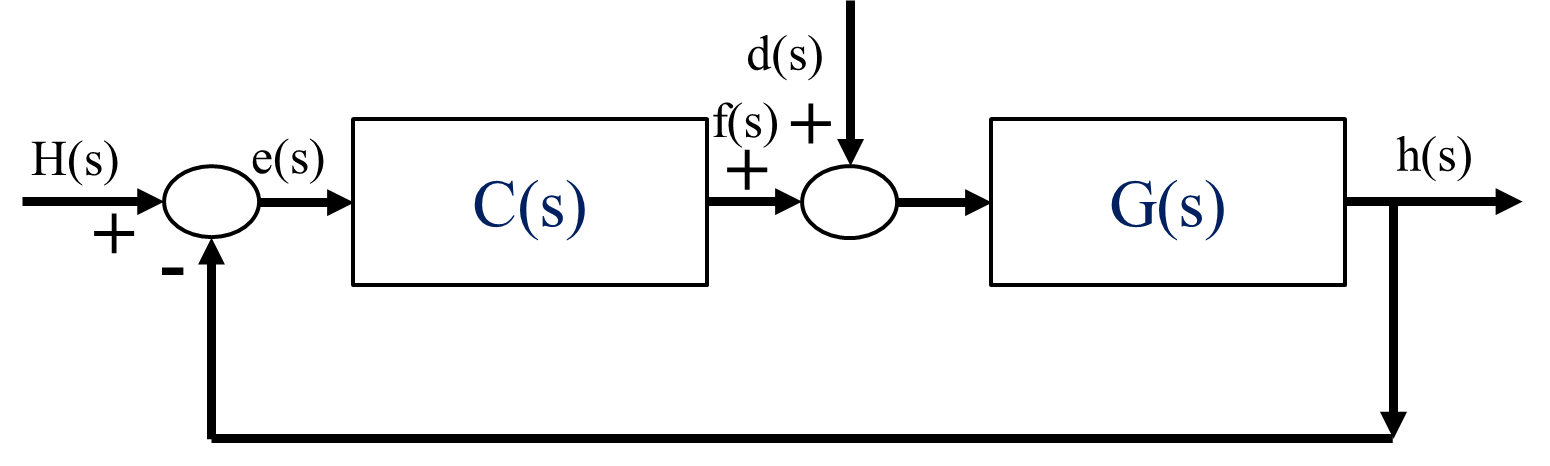

### 1.5. Closed-loop behaviour analysis

The closed-loop transferences for the block diagram above can be summarised as:

$Y_r \left(s\right)=G_c \left(s\right)H\left(s\right)$ with   $G_c =\frac{\textrm{GC}}{1+\textrm{GC}}$         Dependence of depth on the target.

$U_r \left(s\right)=G_{\textrm{cu}} \left(s\right)H\left(s\right)$ with   $G_{\textrm{cu}} =\frac{C}{1+\textrm{GC}}$    Dependence of flow-in term on the target.

$Y_d \left(s\right)=G_{\textrm{cd}} \left(s\right)d\left(s\right)$ with   $G_{\textrm{cd}} =\frac{G}{1+\textrm{GC}}$    Dependence of depth on the disturbance flow.

$U_d \left(s\right)=G_{\textrm{cud}} \left(s\right)d\left(s\right)$ with   $G_{\textrm{cud}} =\frac{-\textrm{GC}}{1+\textrm{GC}}$    Dependence of in-flow* f * on the disturbance flow *d*.

The total depth and in-flow is computed from superposition, hence:


$$h=Y_r +Y_d ;\;\;\;f=U_r +U_d$$


**Remark**: For more information, indicative code and examples on PI design and analysis, look at the app: ***tanklevel_and_PIcontrol.mlapp***.

### 1.6 Impact of delays

Real systems will often have some form of measurement delay. This could just be because the sensor is slow to respond to changes in the output, and indeed a number of other possible causes. The consequence of this is that the control decisions are based on out of date measurements.  Simplified analysis can be undertaken to study this by replacing the transfer function G(s) in section 1.5 above as follows.

$G\left(s\right)\longrightarrow G\left(s\right)e^{-\mathrm{sT}}$  where T is the delay.

**Remark**: For convenience, this app describes delay by the number of samples ('n') as the implementation is done in a discrete fashion with a fixed sample rate of $T_{\mathrm{samp}} =0\ldotp 5\;\Rightarrow T=\frac{n}{2}$ sec ($T_{\mathrm{samp}}$ can be changed in the file header).

## 2. Using the app for manual control

There is a need to get the tank level to a given value, notwithstanding all the external disturbances. In principle on easy way to achieve this is to have a human operator changing the in-flow. The operator observes the depth and decides what in-flow is required. It would be normal to assume that he operator does not have direct knowledge of the disturbances (blockages and additional flows) and can only infer these indirectly from measurements of the depth response.

The app provides a slider (the vertical one) that users adjust manually during the simulation to control the depth.Users can try this with a variety of disturbance magnitudes and tank dimensions and explore how effective they are in achieving this. To make this realistic, it is important that the operator focuses SOLELY on the picture of the tank and the level there and tries to ignore the other figures which are for information post experiment. Especially when the delay is significant, it will quickly apparent how difficult it is to achieve effective depth control when the disturbances are changing significantly (maximum magnitudes set in the green box).

- Try with zero disturbances and zero delay.

- Try with small disturbances and no delay.

- Try with big disturbances and no delay.

- Try above with a delay added; how much has behaviour changed?

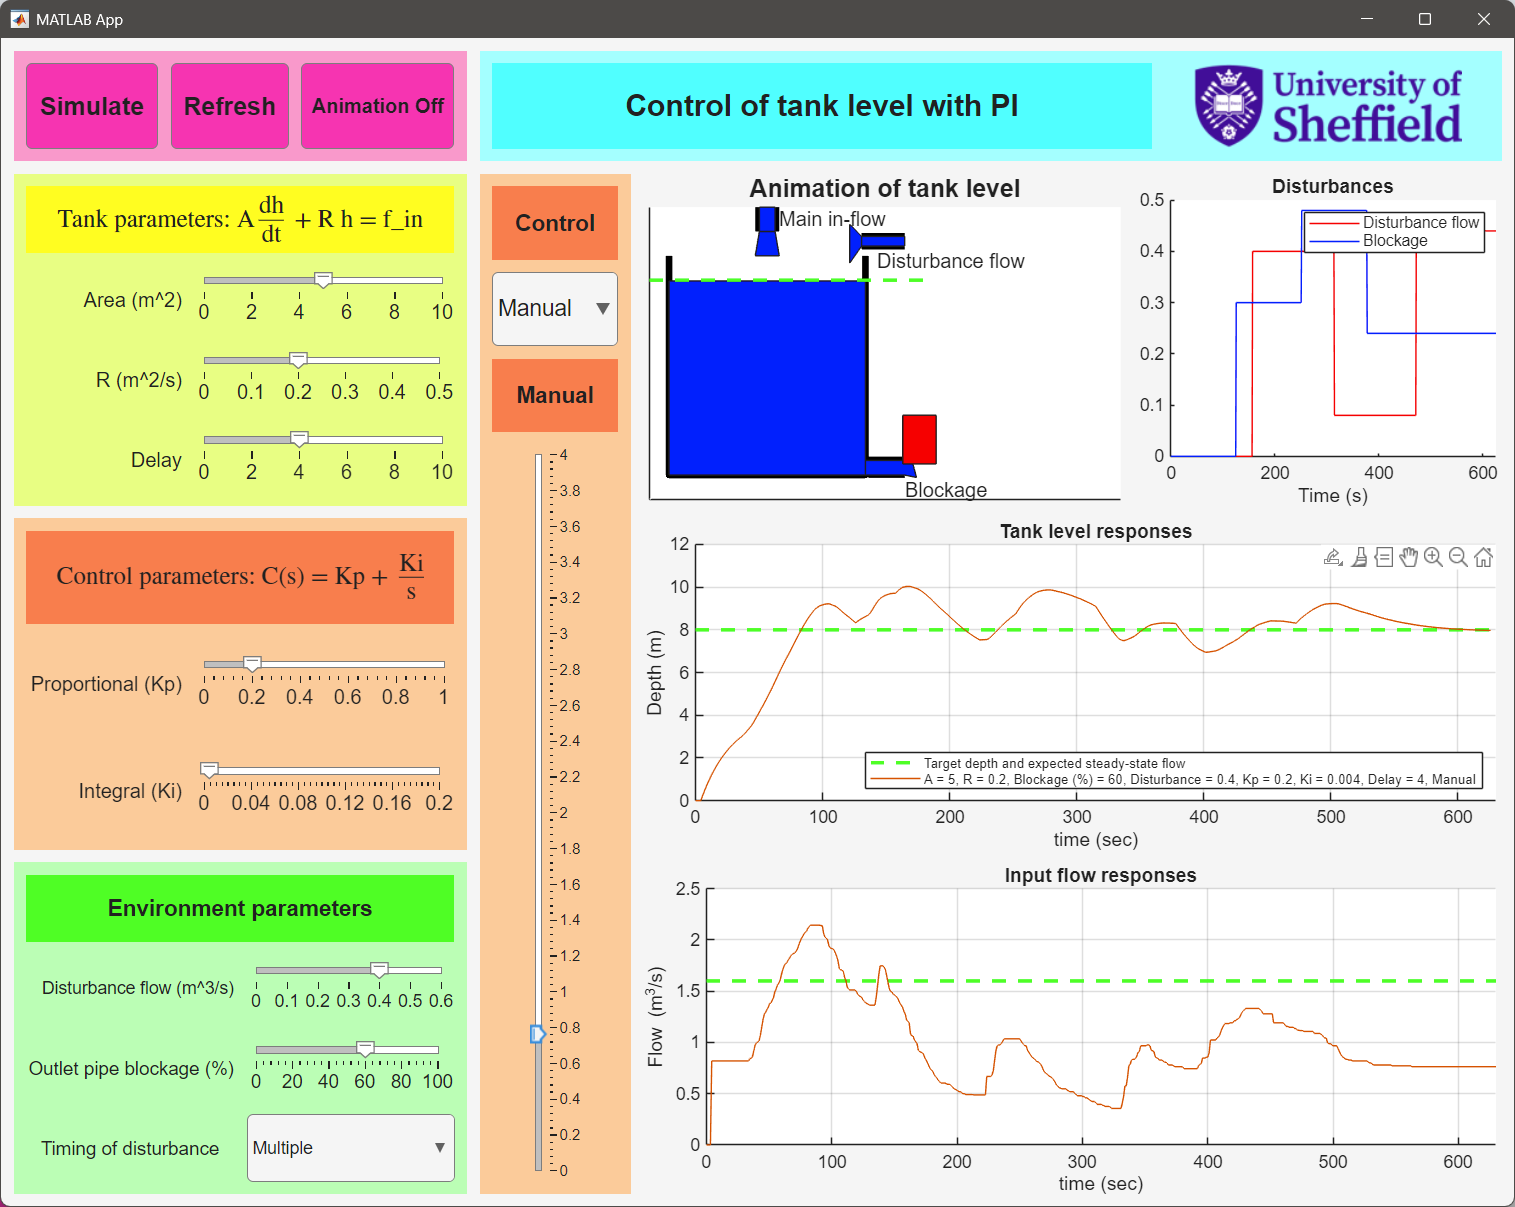

## **3. Using the app for PI control**

As the PI solutions can be computed very quickly, the USER may choose to switch the animation off for these simulations to save time and go straight to the figures. PI parameters are chosen in the orange box.

Above the vertical  slider you will see a drop down that allows the selection of PI control in place of manual. The legend within the fugures stores the options selected so that the USER can compare and contrast different simulations. In the figure here, it is apparent that the automatic PI control has kept the level deviations smaller on average than manual control.